#### Assignment 3 : Case Studies

Conjugate Gradient

Question 1

% Question 1

function [x,k,diff] = CG_algorithm(A, b, tol, max_iter)
    N=size(A,1);
    x0 = zeros(N, 1);
    r0 = b-A*x0;
    p0 = r0;
    
    x = x0;
    
    for j = 1:max_iter
        diff = dot(r0,r0);
        k = j;
        if diff<tol
            break
        end
        alpha = dot(r0,r0)/dot(A*p0,p0);
        x = x + alpha*p0;
        r1 = r0 - alpha*A*p0;
        beta = dot(r1,r1)/dot(r0,r0);
        p0 = r1 + beta*p0;
        r0 = r1;
    end
end

Question 2

for N = [1024, 500, 200]
    tol = 10e-8;
    tau = 20;
    noise = 0.005;
    [A,b]= get_covariance_matrix(N,tau,noise);
    max_iter = 1000;
    
    [~,k,diff] = CG_algorithm(A, b, tol, max_iter);
    
    if k<max_iter
        fprintf("N = %i : Algorithm converged : k = %i and diff = %i\n", N, k, diff);
    else
        fprintf("N = %i : Algorithm did not converge\n", N);
    end
end

N = 1024 : Algorithm converged : k = 368 and diff = 7.722446e-08
N = 500 : Algorithm converged : k = 227 and diff = 8.388420e-08
N = 200 : Algorithm converged : k = 102 and diff = 3.429176e-08


Question 3

The last three digits of my tcd number are : 026

list_noise = linspace(0.5*exp(-8), 0.5, 5);
for noise = list_noise
    tol = 10e-8;
    tau = 026;
    N = 1024;
    [A,b]= get_covariance_matrix(N,tau,noise);
    max_iter = 2000;
    
    [~,k,~] = CG_algorithm(A, b, tol, max_iter);
    
    if k<max_iter
        fprintf("noise = %i : Algorithm converged : k = %i, kappa = %i\n", noise, k, max(eig(A))/min(eig(A)));
    else
        fprintf("noise = %i : Algorithm did not converge\n", noise);
    end
end

noise = 1.677313e-04 : Algorithm converged : k = 1715, kappa = 3.105257e+05
noise = 1.251258e-01 : Algorithm converged : k = 87, kappa = 4.784308e+02
noise = 2.500839e-01 : Algorithm converged : k = 67, kappa = 2.398990e+02
noise = 3.750419e-01 : Algorithm converged : k = 56, kappa = 1.603069e+02
noise = 5.000000e-01 : Algorithm converged : k = 50, kappa = 1.204955e+02



$$\mathcal{A}(x,x')= \left( 1+\frac{\sqrt{3}||x-x'||}{\tau}\right) \exp\left(-\frac{\sqrt{3}||x-x'||}{\tau}\right)+\varepsilon I$$


As $\varepsilon$(noise) decrease, the number of iterations will increase.

Let $K = \left( 1+\frac{\sqrt{3}||x-x'||}{\tau}\right) \exp\left(-\frac{\sqrt{3}||x-x'||}{\tau}\right)$and $\lambda_i(K)$ its eigen values.

Then the eigen values of $\mathcal{A}$ are $\lambda_i(\mathcal{A})=\lambda_i(K) + \varepsilon$

The condition number of $\mathcal{A}$ is $\kappa(\mathcal{A})=\frac{\max(\lambda_i(\mathcal{A}))}{\min(\lambda_i(\mathcal{A}))}$ so if the noise is near 0, the condition number will explode (as the smallest eigen value gets closer to 0).

Since the convergence of the algorithm is determined by the condition number of $\mathcal{A}$, then the algorithm wil take more iterations to converge if the noise is near 0.

**Question 4**

N = 1024;
tau = 100;
noise = 0.05;

[A,b] = get_covariance_matrix(N, tau, noise);

tol = 10e-8;
max_iter = 1000;

[~,k,diff] = CG_algorithm(A, b, tol, max_iter);

if k<max_iter
    fprintf("A : Algorithm converged : k = %i, kappa = %i\n", k, max(eig(A))/min(eig(A)));
else
    fprintf("A matrix : Algorithm did not converge\n");
end

A : Algorithm converged : k = 85, kappa = 4.402364e+03



M=chol(A);
A_new = M \ (A / M');

[~,k_new,diff_new] = CG_algorithm(A_new, b, tol, max_iter);

if k_new<max_iter
    fprintf("A_new : Algorithm converged : k = %i, kappa = %i\n", k, max(eig(A_new))/min(eig(A_new)));
else
    fprintf("A_new : Algorithm did not converge\n");
end

A_new : Algorithm converged : k = 85, kappa = 4.583756e+04


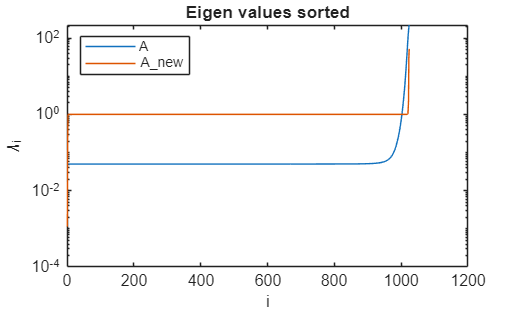


semilogy(sort(eig(A)), 'DisplayName', 'A');
hold on
semilogy(sort(abs(eig(A_new))), 'DisplayName', 'A\_new');
hold off
title('Eigen values sorted')
legend('Location', 'northwest');
xlabel('i')
ylabel('\lambda_i')

Both marices have similar eigen values: the eigen values stays at one constant value ($0.05$ for $\mathcal{A}$ matrix and $1$ for A_new matrix) and have a few extremes ($10^2$ for $\mathcal{A}$ and A_new, and $10^{-3}$ for A_new). 

However, the condition numbers are quite different : $\kappa(\mathcal{A})\approx 10^3$ and $\kappa(\text{A\_new}) \approx 10^4$ which is strange because both matrices have the exact same iterations before convergence.